clear variables;

x = 1:5;
y = sin(x);

plot(x, y);

f = fit(x', y', 'fourier1')

f =      General model Fourier1:
     f(x) =  a0 + a1*cos(x*w) + b1*sin(x*w)
     Coefficients (with 95% confidence bounds):
       a0 =   7.811e-09  (-3.461e-07, 3.617e-07)
       a1 =   -1.14e-07  (-1.661e-06, 1.433e-06)
       b1 =           1  (1, 1)
       w =           1  (1, 1)

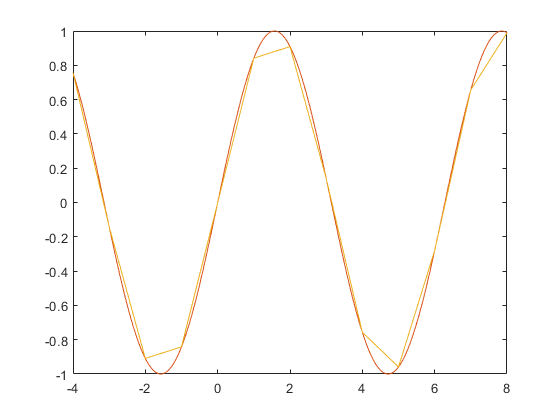


x1 = -4:8;
y1 = f.a0 + f.a1 * cos(x1*f.w) + f.b1 * sin(x1*f.w);

hold on;
plot(-4:0.01:8, sin(-4:0.01:8))
plot(x1, y1)